# Collaborate@ICERM 2026

## Infinite Channel using Bernardi Formulation for BCs

## Boundary Velocity

The velocity at the top and bottom boundary are given by:


$$v(x,\pm H) = \left\{ \begin{array}{lr} 0, & x\in[-L-c,-L]\cup [L,L+c]\\ \pm {\rm Da}\, p_T(x) & x\in(-L,L) \end{array} \right.$$


Following Bernardi: 


$$p_T(x,\pm H) = \left\{ \begin{array}{lr} -Gx - GL +  \frac{G}{\lambda}\tanh(\lambda L), & x\in (-L-c,-L)\\ -\frac{G}{\lambda\cosh(\lambda L)}\sinh(\lambda x) & x\in(-L,L) \\ -Gx+ GL- \frac{G}{\lambda}\tanh(\lambda L), & x\in (L,L+c)\end{array} \right.$$


where $\lambda$ satisfies $0=({\rm Da}-H/2)\lambda\cot(\lambda H)\cos(\lambda H) + \frac12\cos(\lambda H)-\frac{\lambda H}{2}\sin(\lambda H)$. (Note: For ${\rm Da}=0.3, H=1$, we have $\lambda\approx 0.74$.)

In the non-permeable region, we have $v=0$ and $u=0$. At the inlet, we have fully developed Poiseuille flow ($u=u_{pois}$, $v=0$). At the outlet, the Poiseuille flow is scaled by a factor $\chi$ to give $u=\chi u_{pois}$ and $v=0$.

The velocity boundary conditions in this instance are


$$v(x,\pm H) = \left\{ \begin{array}{lr} 0, & x\in[-L-c,-L]\cup [L,L+c]\\ \mp\frac{{\rm Da} \, G}{\lambda\cosh(\lambda L)}\sinh(\lambda x) & x\in(-L,L) \end{array} \right.$$


$u(x,\pm H) = 0\quad\text{for}\quad x\in[-L-c,L+c]$.

## Permeable wall computation

clear
close all 

addpath('../stokeslets_codes'); 

method_for_plots = 'St+SD Pozrikidis Set-up';

#### **Set parameters**

- Blob choice 2 uses $\psi$ from 2021 paper

- Blob choice 1 uses $\phi$ from 2021 paper

%set Darcy number
Da = 0.3;
%viscosity
mu = 1; 
% Regularization parameter
blob_num = 2; % blob choice
ep_factor = 1; 
ep_d_factor = 1; 
%C = 0.04*5.75; % constant for beta_value; 
C = 0.04*8.5; %constant for beta_value when V = 0 (velocity for Step 1 permeable) 
% Poiseuille flow strength
pL=10;
% chi in PC paper: "dimensionless coeff. determining exit flow rate
exit_rate = 1;

% Number of source and target points
N = 160; % Number of source points (along top  and bottom boundaries)
Nx2 = 80; % Number of target points in y direction for full channel calc
Nx1 = floor(2*pi*Nx2); % Number of target points in x direction for full channel calc

#### **Define geometry and regularization**

% Setting forces and computing velocity 
%channel geometry
L = 3; % length of permeable region
H = 1; % height of channel
c = 2*H; % length of nonpermeable region on one side (scale factor of H based on Pozrikidis)
xmin = 0;
xmax = xmin + L + 2*c;
ymin = 0;
ymax = ymin + 2*H;
perm_min = c;         %start of permeable part
perm_max = L + c;  %end of permeable part

scalefactor = 0.05; % for the boundary velocity figures (why?)

% Discretization step
ds_x = (xmax - xmin)/N;
ds_y = (ymax - ymin)/( ceil((ymax - ymin)/ds_x));

% Define blob size based on wall discretization 
ep = ds_y*ep_factor;
ep_d =ep*ep_d_factor; 

% beta value based on Da, epsilon, and C
beta_value = Da*ep*C;

#### **Discretization**

tb = top/bottom

lr = left/right

source point coordinates organized stacked:

    [top; bottom; left; right]

%discretization step of top/bottom walls
stb = xmin+ds_x/2:ds_x:xmax-ds_x/2;
stb = stb';
%discretization step of left/right wall (inlet/outlet)
slr = ymin+ds_y/2:ds_y:ymax-ds_y/2;
slr = slr';

% Define coordinates on each wall (x-coord,y-coord) (source points)
y1_top = stb;   y2_top = ymax*ones(size(stb)); % top wall coordinates (y1_top,y2_top)
y1_bot = stb;   y2_bot = ymin*ones(size(stb)); % bottom wall coordinates (y1_bot,y2_bot)
y1_left = xmin*ones(size(slr));   y2_left = slr; % left wall coordinates (y1_left,y2_left)
y1_right = xmax*ones(size(slr));   y2_right = slr; % right wall coordinates (y1_right,y2_right)
y1 = [y1_top; y1_bot; y1_left; y1_right]; %x-coordinates of all boundary points
y2 = [y2_top; y2_bot; y2_left; y2_right]; %y-coordinates of all boundary points

% Define normal vectors
normals_top = zeros(length(stb),2); % unit normals for top:
normals_top(:,2) = 1;
normals_bot = zeros(length(stb),2); % unit normals for bottom
normals_bot(:,2) = -1;
normals_left = zeros(length(slr),2); % unit normals for left  wall 
normals_left(:,1) = -1;
normals_right = zeros(length(slr),2); % unit normals for right wall 
normals_right(:,1) = 1;

% normals on full boundary
normals = [normals_top; normals_bot; normals_left; normals_right];

% Points where velocity will be computed within the channel (target points)
xx1 = linspace(xmin,xmax,Nx1);
xx2 = linspace(ymin,ymax,Nx2);
[x1m, x2m] = ndgrid(xx1, xx2);
x1 = x1m(:); %x-coords of points where computing velocity
x2 = x2m(:); %y-coords of points where computing velocity
dx_g = xx1(2)-xx1(1); %(xx1(end)-xx1(1))/Nx1;
dy_g = xx2(2)-xx2(1); %(xx2(end)-xx2(1))/Nx2;

#### **Set boundary velocities and beta**

% Define quadrature weights cooresponding to wall coordinates.
% Currently using midpoint rule.
% Weights for targets/sources at corners and just outside inlet/outlet are
% set to ds_y (possibly not correct) but will be divided out so shouldn't cause issues.
wt = [ds_x*ones(size(y1_top)); ds_x*ones(size(y1_bot)); ds_y*ones(size(y1_left)); ds_y*ones(size(y1_right))];

% No slip at top and bottom 
% (set to 0, although technically unknown in permeable region)
u1_top_exact = zeros(size(y1_top)); u2_top_exact = zeros(size(y2_top));
u1_bot_exact = zeros(size(y1_bot)); u2_bot_exact = zeros(size(y2_bot));
% Poiseuille flow at inlet and outlet
u_pois = -pL*(y2_left - ymin).*(y2_left - ymax);%/2/mu;
u1_left_exact = u_pois;
u1_right_exact = exit_rate*u_pois;
u2_left_exact = zeros(size(slr));
u2_right_exact = zeros(size(slr));

% Set zero velocity contribution from stokeslets on permeable parts
u1 = [u1_top_exact; u1_bot_exact; u1_left_exact; u1_right_exact];
u2 = [u2_top_exact; u2_bot_exact; u2_left_exact; u2_right_exact];

permidx = find(c < y1 & y1 < L+c);
beta = zeros(length(y1),1);
beta(permidx) = beta_value;

#### **Find forces on boundary due to known velocities**

% Now we utilize the Stokeslets + Source Doublets approach to simulate the
% permeable channel flow

% 4-Step Permeable Channel Process: Input and output velocities are the known (exact)
% velocities on left and right, and zero for unknown velocities on top and
% bottom (where it's permeable).

% STEP 1: Find g-force distribution due to St+SD on solid walls and SD (no
% Stokeslets) on permeable walls
%[g] = RegStokeslets2D_velocityto_gforce_permeable([y1,y2],[y1,y2],...
%    [u1,u2], ep, mu, blob_num, idx, beta, normals, wt);
[g] = RegStokeslets2D_velocityto_gforce_SK([y1,y2], [y1,y2], [u1,u2],ep,ep_d,mu,blob_num, permidx, beta, normals, wt); 

log10 of condition number of Mat: 3.5147
condition number of Mat+D: 3208.1365
size of Mat+D: 824  824
log10 of condition number of Mat+D: 4.6451
condition number of Mat+D: 44166.1898
size of Mat+D: 824  824


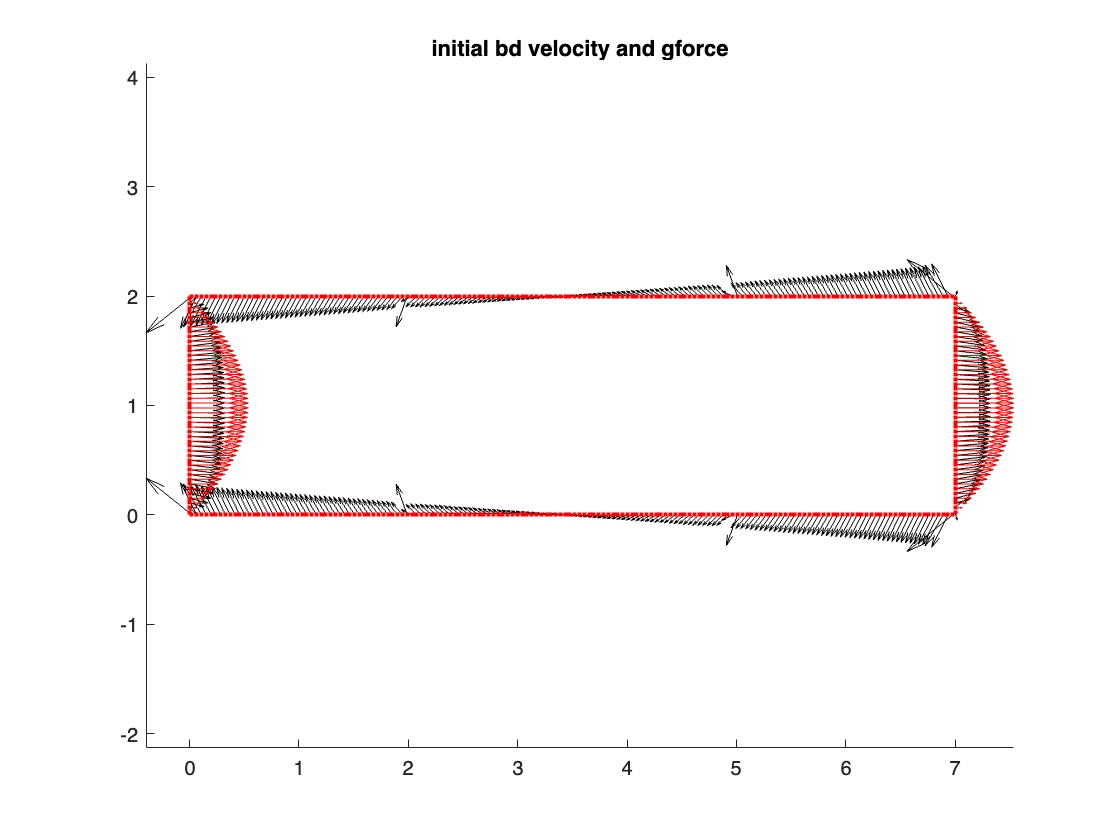

g1 = g(:,1);
g2 = g(:,2);
y1gforce = y1;
y2gforce = y2;

% Plot g forces
figure;
sk = 1;
scaleFactor = 3;
hold on
quiver(y1gforce(1:sk:end),y2gforce(1:sk:end),g1(1:sk:end),g2(1:sk:end),1.5,'k','AutoScale','off')
quiver(y1(1:sk:end),y2(1:sk:end),u1(1:sk:end),u2(1:sk:end),1.5,'r','AutoScale','off')
plot(y1gforce(1:sk:end),y2gforce(1:sk:end),'r.')
axis equal
title('initial bd velocity and gforce')

%axis([-4,4,-1.5,1.5])
% STEP 2: Use g on full boundary to find missing velocities on permeable walls

% Boundary points for permeable section
y1b=y1(permidx);
y2b=y2(permidx);

% Inputs to function are source, g force, target, ...
[u_perm] = RegStokeslets2D_gtovelocity([y1,y2], g, [y1b,y2b], ep_d, mu, blob_num, beta, normals, wt);
u_perm1 = u_perm(:,1);
u_perm2 = u_perm(:,2);

% Replace the placeholder zeros in u1,u2 with the velocities
% [zeros(size(u1_top_exact)); zeros(size(u1_bot_exact)); u1_left_exact; u1_right_exact; zeros(size(u1_corner_exact))]; %x-coordinates of all boundary velocities
u1(permidx) = u_perm1;
u2(permidx) = u_perm2;


% Step 3: Use boundary velocities to solve for forces on boundary

% Now that the missing velocities are recovered, steps 3-4 are the regular
% "Stokeslet" problem, given boundary velocities, find boundary forces,
% then find channel velocities.
ftemp = RegStokeslets2D_velocitytoforce_KK([y1,y2], [y1,y2], [u1,u2], ep, mu, blob_num,wt);

log10 of condition number of Mat: 3.5113
condition number of Mat+D: 3245.7131
size of Mat+D: 824  824


#### **Compute velocity and pressure everywhere due to boundary forces**

% Step 4: compute velocity everywhere using the computed forces
ug = RegStokeslets2D_forcetovelocity([y1,y2],ftemp,[x1,x2],ep,mu,blob_num,wt);
ug1 = ug(:,1);
ug2 = ug(:,2);
u1m = reshape(ug1,size(xx1,2),size(xx2,2)); % x-coords of computed velocities everywhere
u2m = reshape(ug2,size(xx1,2),size(xx2,2)); % y-coords of computed velocities everywhere
ummag = sqrt(u1m.^2 + u2m.^2);

% computed pressure
p = RegStokeslets2D_forcetopressure([y1,y2], ftemp, [x1, x2], ep, mu, blob_num, wt);
pm = reshape(p,size(xx1,2),size(xx2,2));

### Compute fluxes

% Compute numerical flux
idx_flux = find(y1_top < c+L/2 & y1_top > c);
y1_flux = y1_top(idx_flux);
normals_flux = zeros(length(y1_flux),2);
normals_flux(:,2) = 1;
Rtop = ds_x*sum(dot(normals_flux, [zeros(size(y1_flux)), u_perm2(idx_flux)]));

### Plotting

#### Streamlines of Exact and Computed 

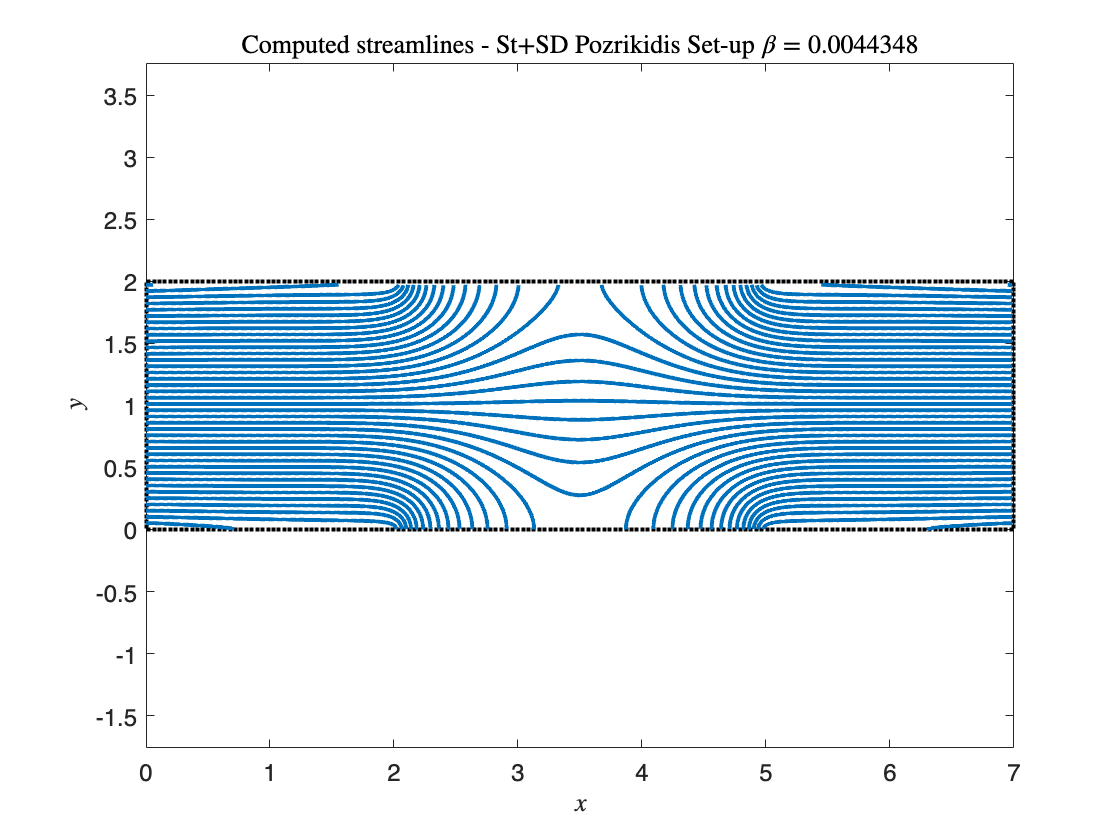

[x1gg, x2gg] = meshgrid(xx1, xx2);

figure
plot_streamline_computed(u1m,u2m,x1gg,x2gg,y1,y2,method_for_plots,beta_value)

#### Quiver plot of exact velocities on boundaries

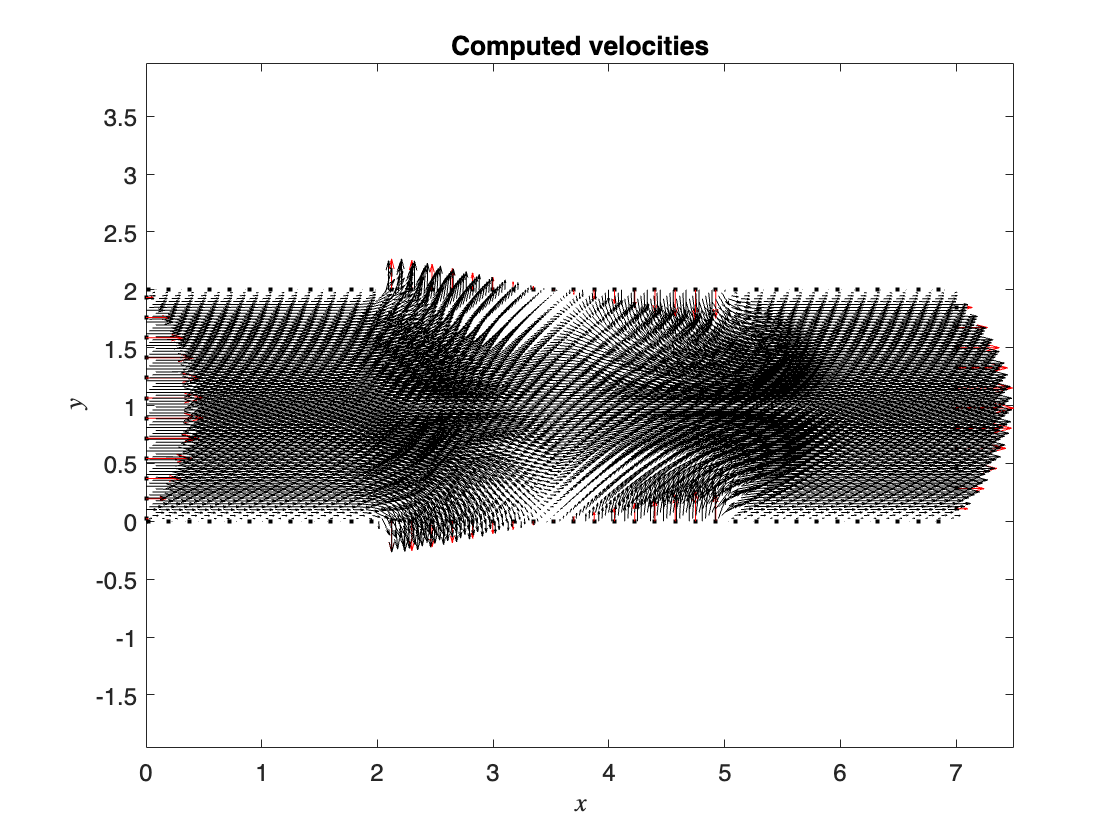

figure
sk = 4;
plot_boundary_quiver(y1(1:sk:end), y2(1:sk:end), x1m(1:sk:end), x2m(1:sk:end), u1(1:sk:end), u2(1:sk:end), u1m(1:sk:end), u2m(1:sk:end), 2)

%plot_boundary_quiver(y1, y2, x1m, x2m, u1m, u2m, 2)

#### pcolor plot of velocities everywhere with quiver of computed forces on boundaries

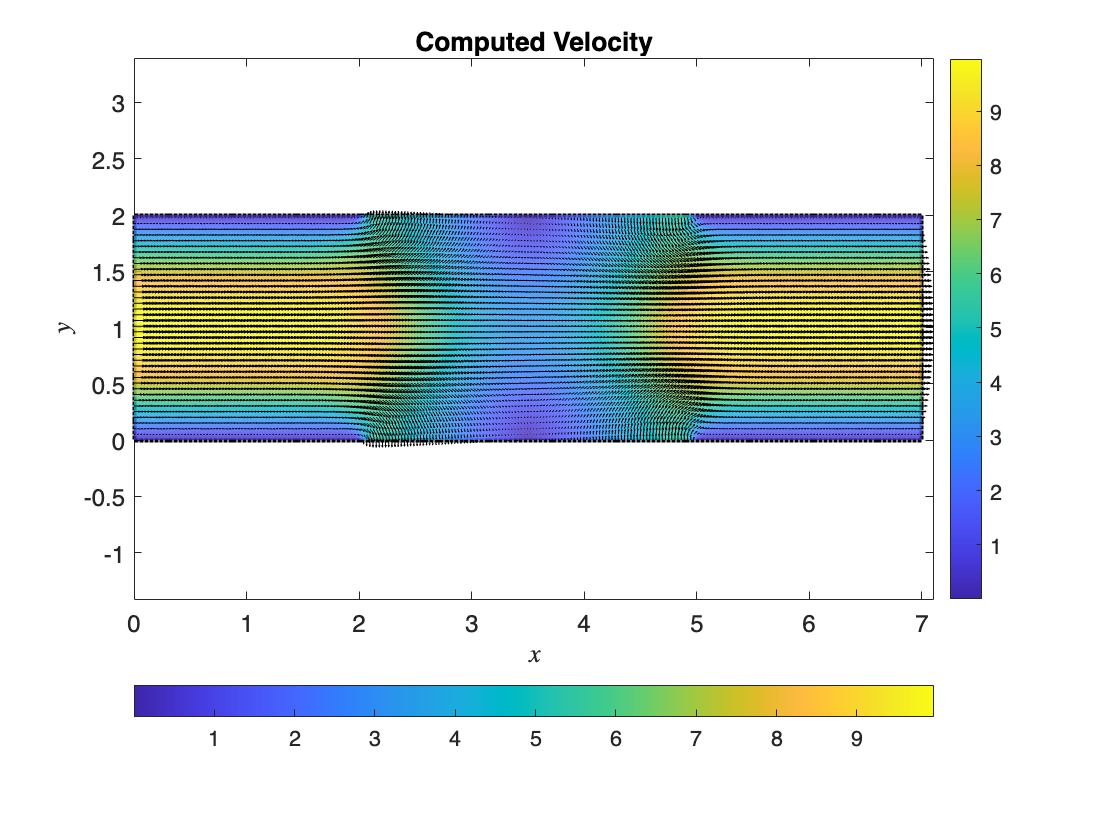

figure
plot_velocity_pcolor(y1,y2,x1m,x2m,u1m,u2m,ummag,2);

#### Calculate Errors and Plot

% get exact solution everywhere
%u_error = uexact - u1m';
%v_error = vexact - u2m';

%calculate_errors(u_error,v_error,xx1,xx2,dx_g,dy_g,y1,y2,method_for_plots)

## Internal functions to be used by notebook

### **Exact Solution from Pozrikidis paper**

function pg = permeablechannelexactCP(x,pL,mu,H,L,Da)
    alpha = sqrt(3*mu*Da/H^3);
    pg = 2*pL*sinh(alpha*x)/sinh(alpha*L);
end

### **Exact Solution from FB paper**

function [ug,vg,pg] = permeablechannelexactFB(x,y,Da)

% Newton's method to find lambda1
L1=sqrt(2*Da);
f=@(L) tan(L)^2-tan(L)/L+1-2*Da;
L1 = fzero(f,L1);
%disp(['lambda_1 = ',num2str(L1)])

% Compute g and g' from FB paper
g  = cot(L1)*(Da-0.5)   *sin(L1*y)+0.5*y.*cos(L1*y);
gp = cot(L1)*(Da-0.5)*L1*cos(L1*y)+0.5*cos(L1*y)-0.5*L1*y.*sin(L1*y);

% Compute exact solution using g and g'
C = -4;   
pg = C*sinh(L1*x) .* cos(L1*y);
ug = -C/L1 * cosh(L1*x) .* gp;
vg =  C    * sinh(L1*x) .* g ;

end

### **Error Calculation**

%% Errors
function [errors] = calculate_errors(u_error,v_error,xx1,xx2,dx,dy,y1,y2,method_name)

scalefactor = 3;
skip = 1;

u_error_max = max(max(abs(u_error)));
v_error_max = max(max(abs(v_error)));
u_error_L1 = dx*dy*sum(sum(abs(u_error)));
v_error_L1 = dx*dy*sum(sum(abs(v_error)));
u_error_L2 = sqrt(dx*dy*sum(sum(u_error.^2)));
v_error_L2 = sqrt(dx*dy*sum(sum(v_error.^2)));
error_mag = sqrt(u_error.^2 + v_error.^2);

ColNames = {'Max','L1','L2'};
Emax = [u_error_max; v_error_max];
EL1 = [u_error_L1; v_error_L1];
EL2 = [u_error_L2; v_error_L2];
errors = table(Emax, EL1, EL2,'VariableNames',ColNames);

figure
subplot(2,2,1);
pcolor(xx1, xx2, u_error)
shading interp
colorbar('southoutside')
title(['Error in u (horizontal) velocity -- ' method_name]);
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal;
set(gca,'FontSize',12)

subplot(2,2,2);
pcolor(xx1, xx2, v_error)
shading interp
colorbar('southoutside')
title(['Error in v (vertical) velocity -- ' method_name]);
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal;
set(gca,'FontSize',12)

subplot(2,2,3);
quiver(xx1(1:skip:end,1:skip:end), xx2(1:skip:end,1:skip:end), u_error(1:skip:end,1:skip:end), v_error(1:skip:end,1:skip:end),scalefactor)
hold on
plot(y1,y2,'.k')
axis equal
ylim([-1.1,1.1])
xlim([xx1(1),xx1(end)])
title('Quiver of errors')
set(gca,'FontSize',12)

subplot(2,2,4);
pcolor(xx1, xx2, error_mag)
shading interp
colorbar('southoutside')
title(['Magnitude of Error in Velocity -- ' method_name]);
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal;
set(gca,'FontSize',12)

end

### **Generate Streamline Plots**

function plot_streamline_computed(u1m,u2m,x1gg,x2gg,y1,y2,method_name,beta_value)

plot(y1, y2, 'k.')
hold on

x1gg = x1gg(1:2:end,1:2:end);
x2gg = x2gg(1:2:end,1:2:end);
u1m = u1m(1:2:end,1:2:end);
u2m = u2m(1:2:end,1:2:end);

% Computed streamlines
hh1_comp = streamline(x1gg, x2gg, u1m', u2m', x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_comp = streamline(x1gg, x2gg, -u1m', -u2m', x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall

strmLW = 2;
RGB = orderedcolors("gem");
set(hh1_comp, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh2_comp, 'Color', RGB(1,:), 'linewidth', strmLW);

title(['Computed streamlines - ' method_name, ' $\beta=$', num2str(beta_value)],'interpreter','latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
%axis([x1gg(1),x1gg(end),-1.5,1.5])
set(gca,'FontSize',12)

end

%% Streamline Plot function for exact solution and computed
function plot_streamline(u1m,u2m,x1gg,x2gg,uexact,vexact,y1,y2,method_name)

plot(y1, y2, 'k.')
hold on

% Computed streamlines
hh1_comp = streamline(x1gg, x2gg, u1m', u2m', x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_comp = streamline(x1gg, x2gg, -u1m', -u2m', x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall
% Exact streamlines
hh1_exact = streamline(x1gg, x2gg, uexact, vexact, x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_exact = streamline(x1gg, x2gg, -uexact, -vexact, x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall

strmLW = 2;
RGB = orderedcolors("gem");
set(hh1_comp, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh2_comp, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh1_exact, 'Color', RGB(3,:), 'LineStyle','--', 'linewidth', strmLW);
set(hh2_exact, 'Color', RGB(3,:), 'LineStyle','--', 'linewidth', strmLW);

title(['Computed (blue) and exact (yellow) streamlines - ' method_name])
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
axis([x1gg(1),x1gg(end),-1.5,1.5])
set(gca,'FontSize',12)

end

### **Generate Quiver Plots on Boundaries**

%% Streamline Plot function
function plot_boundary_quiver(y1, y2, x1m, x2m, u1_exact, u2_exact, u1m, u2m, skip)
%function plot_boundary_quiver(y1, y2, x1m, x2m, u1m, u2m, u1, u2, skip)

scalefactor = 0.05;

plot(y1,y2,'k.')
hold on
quiver(y1,y2,u1_exact*scalefactor,u2_exact*scalefactor,'r','AutoScale','off')
hold on
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m(1:skip:end,1:skip:end)*scalefactor,u2m(1:skip:end,1:skip:end)*scalefactor,'k','AutoScale','off')

title('Computed velocities')
%legend('','Exact velocity', 'Computed velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
%axis([x1m(1),x1m(end),-1.5,1.5])
set(gca,'FontSize',12)
end


### **Quiver plot with pcolor velocity**

function plot_velocity_pcolor(y1,y2,x1m,x2m,u1m,u2m,ummag,skip)

scalefactor = 0.7;

plot(y1,y2,'k.')
hold on
pc = pcolor(x1m,x2m,ummag);
set(pc,'facealpha',0.8)
shading interp
colorbar('southoutside')
set(gca,'FontSize',12)

axis equal
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m(1:skip:end,1:skip:end),u2m(1:skip:end,1:skip:end),scalefactor,'k','AutoScale','off')
colorbar
title('Computed Velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca,'FontSize',12)
end
